# MATLABエージェントによるAlgorithm3の実装

## 環境の宣言

A = [-1 2; 2.2 1.7];
B = [2; 1.6];
C = [1 2];
F = -1;

T = blkdiag(A, F);
B1 = [B; 0];
C1 = [C -1];

### 報酬関数の設計

Q = 6;
R = 1;

Q1 = C1'*Q*C1;

### 環境のインスタンス

env = myDiscreteEnv(T,B1,Q1,R);
rng(0)

## エージェントの作成

% K0 = place(A,B,[0.4,0.8,0.5]);
K0 = [0.3 1.3 0.75];
agent = LQTAgent(Q1,R,K0);

## エージェントの学習

trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',1, ...
    'MaxStepsPerEpisode',1000, ...
    'Verbose',true, ...
    'Plots','none');

trainingStats = train(agent,env,trainingOpts);

Episode:   1/  1 | Episode Reward : -5226158080.00 | Episode Steps: 1000 | Avg Reward : -5226158080.00 | Step Count : 1000


## シミュレーション結果の検証

simOptions = rlSimulationOptions('MaxSteps', 100);
experience = sim(env,agent,simOptions);
totalReward = sum(experience.Reward)

totalReward = single
-8.5018e+03

% [Koptimal,P] = dlqr(T,B1,Q1,R);
Koptimal = [-0.1898 1.0085 -0.0640];
x0 = experience.Observation.obs1.getdatasamples(1);
% Joptimal = -x0'*P*x0;
% rewardError = totalReward - Joptimal

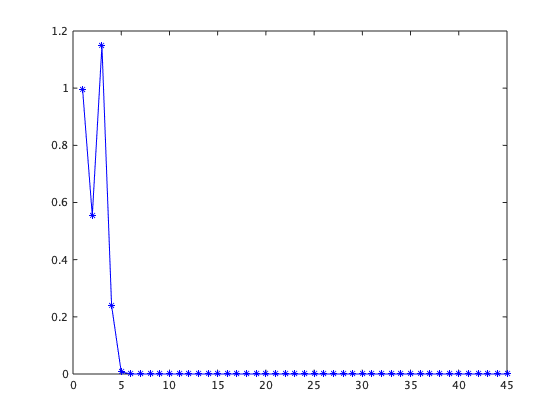

% number of gain updates
len = agent.KUpdate;
err = zeros(len,1);
for i = 1:len
    % norm of error in the gain
    err(i) = norm(agent.KBuffer{i}-Koptimal);
end  
plot(err,'b*-')

gainError = norm(agent.K - Koptimal)

gainError = single
6.6796e-05